# Phase Portrait for Spring Mass

clear; close all; clc

% creates two matrices:
% one for all the x-values on the grid (constant columns)
% one for all the y-values on the grid (constant rows)
y1 = linspace(-2.5,2.5,10);
y2 = linspace(-2.5,2.5,10);
[X,Y] = meshgrid(y1,y2);

Computing the Vector Field

% Generate two matrices, u and v. 
% U contains the value of y1'(0) at each x and y position
% V contains the value of y2'(0) at each x and y position
U = zeros(size(X));
V = zeros(size(Y));
t = 0;

% numel iterates over the 1st column, then 2nd, ...
% (could probably use gradient() instead)
for i = 1:numel(X)
    y_dot = f(t, [X(i); Y(i)]); % state space equation
    U(i) = y_dot(1);
    V(i) = y_dot(2);
end

Plot the Vector Field

quiver(X,Y,U,V,'k');
xlabel('x_1 (m)')
ylabel('x_2 (m/s)')
axis equal
title('Vector Field for Spring Mass Oscillator')
subtitle('$k=1, m=1$','Interpreter','latex')

Plotting solutions on the vector field for different initial conditions:

 
$$y_1(0)=y_{10}, \\
y_2(0)=0$$


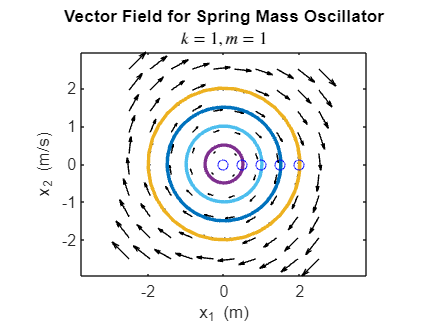

hold on
for y10 = 0:0.5:2
    [ts,ys] = ode45(@f,[0 4*pi],[y10; 0]);
    plot(ys(:,1),ys(:,2),'LineWidth',2)
    plot(ys(1,1),ys(1,2),'bo') % starting point
end
hold off

function [y_dot] = f(~,y)
m=1;
k=1;

y_dot(1,:) = y(2);
y_dot(2,:) = -k/m*y(1);
end
